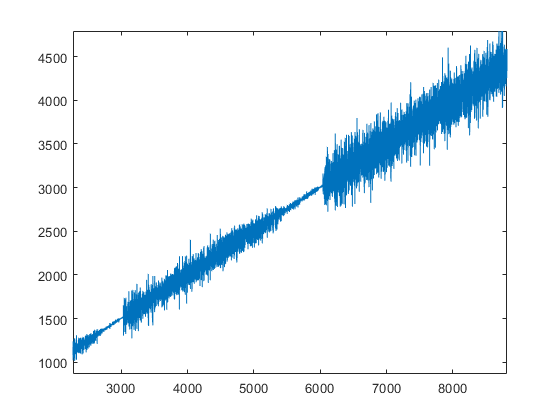

%page 137, 'A chaotic sequence'
%recursive function: Q(n)=Q(n-Q(n-1))+Q(n-Q(n-2)), n>2, Q(1)=Q(2)=1.
A=zeros(10000,1);
for i=1:10000
    A(i)=chaotic(i,A);
end
plot(A)

%we observe that the distance between two consecutive 'bottleneck'points
%is equal to the distance between zero and the first one

function [Q] = chaotic(n,A)
    if n==1
        Q=1;
    elseif n==2
        Q=1;
    else
        a=A(n-1);
        b=A(n-2);
        c=A(n-a);
        d=A(n-b);
        Q=c+d;
    end
end
